clear All
clc

## Importing variety of time series

Importing S&P 500 Daily time series

spx = readmatrix('../data/spx_daily_11-21.csv');
spx = fliplr(transpose(spx(:,2)));
idx = 1:length(spx);
disp("S&P 500 Daily: (length: "+length(spx)+")")

S&P 500 Daily: (length: 2560)


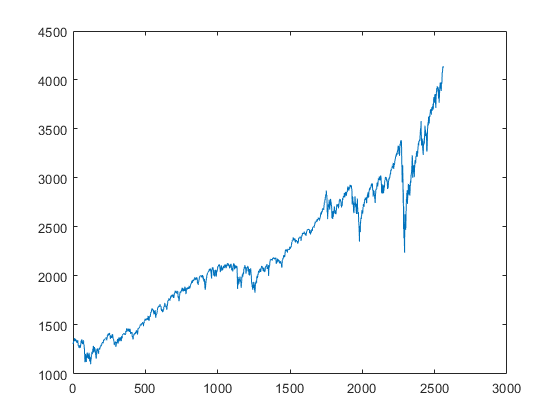

plot(idx,spx)

Importing minimum temperature dataset

min_daily_temp = readmatrix('../data/daily-minimum-temperatures-in-melbourne.csv');
min_daily_temp = transpose(min_daily_temp(:,2));
idx = 1:length(min_daily_temp);
disp("Minimum temperature dataset: (length: "+length(min_daily_temp)+")")

Minimum temperature dataset: (length: 3650)


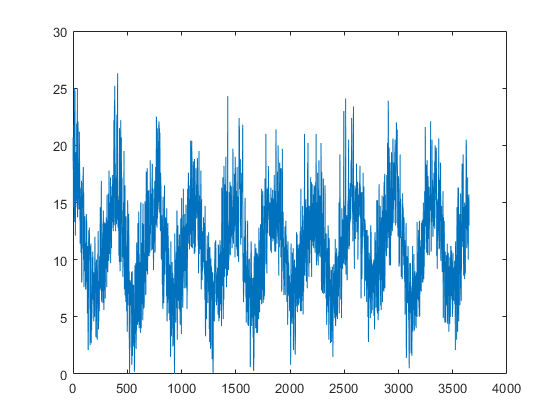

plot(idx,min_daily_temp)

Importing german DAX alltime

dax_alltime = readmatrix('../data/dax_alltime.csv');
dax_alltime = transpose(dax_alltime(:,2));
for i=2:length(dax_alltime)
    if isnan(dax_alltime(i))
        dax_alltime(i) = dax_alltime(i-1);
    end
end
idx = 1:length(dax_alltime);
disp("DAX all time: (length: "+length(dax_alltime)+")")

DAX all time: (length: 8602)


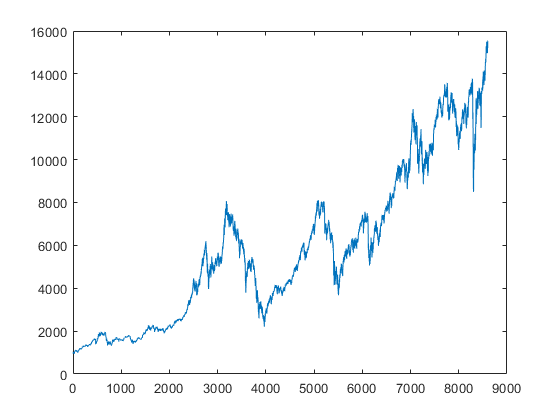

plot(idx,dax_alltime)

Importing Bitcoin alltime

bitcoin_alltime = readmatrix('../data/bitcoin_alltime.csv');
bitcoin_alltime = transpose(bitcoin_alltime(:,2));
for i=2:length(bitcoin_alltime)
    if isnan(bitcoin_alltime(i))
        bitcoin_alltime(i) = bitcoin_alltime(i-1);
    end
end
idx = 1:length(bitcoin_alltime);
disp("Bitcoin all time: (length: "+length(bitcoin_alltime)+")")

Bitcoin all time: (length: 2444)


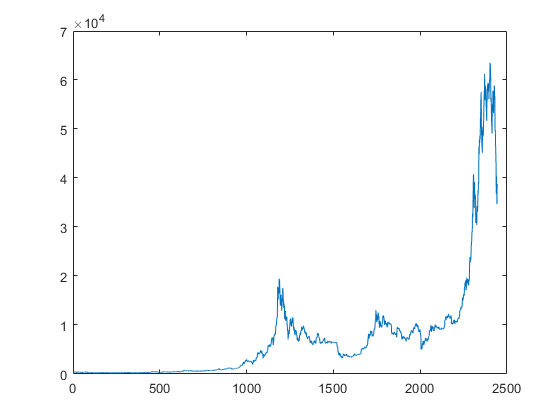

plot(idx,bitcoin_alltime)

Importing hydraulic pressure Data Set

hydraulic = readmatrix('../data/PS1.csv');
hydraulic = transpose(hydraulic(2:length(hydraulic),2));
for i=2:length(hydraulic)
    if isnan(hydraulic(i))
        hydraulic(i) = hydraulic(i-1);
    end
end
idx = 1:length(hydraulic);
disp("Hydraulic pressure data set: (length: "+length(hydraulic)+")")

Hydraulic pressure data set: (length: 6000)


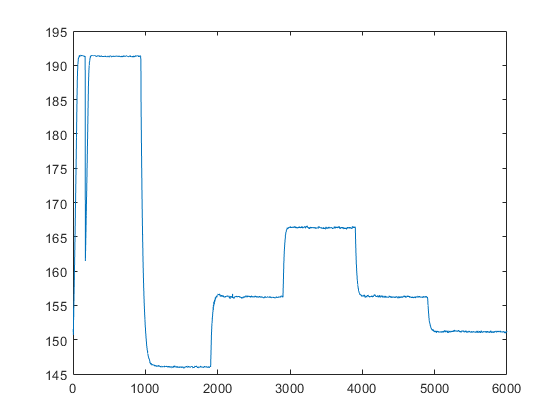

plot(idx,hydraulic)

Importing Beijing O3 in air concentration (quality)

quality = readmatrix('../data/PRSA_Data_Dingling_20130301-20170228.csv');
quality = transpose(quality(:,11));
for i=2:length(quality)
    if isnan(quality(i))
        quality(i) = quality(i-1);
    end
end
idx = 1:length(quality);
disp("Beijing O3 in air concentration : (length: "+length(quality)+")")

Beijing O3 in air concentration : (length: 35064)


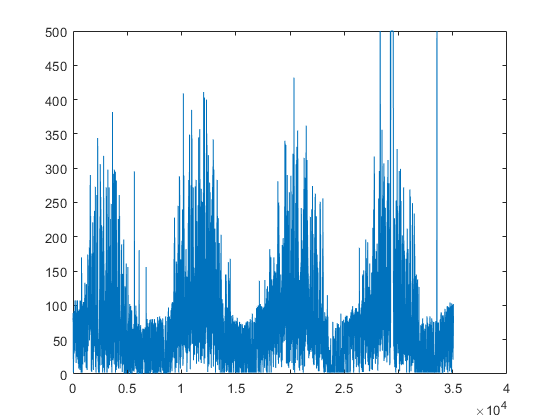

plot(idx,quality)

## Setting hyper parameters for experiment run

% number of iterations of meaningfulness calculation to average over.
n = 10;
% size of cluster set to be calculated for within/between set cluster distance.
r = 3;

ks = [3 5 7 11];
ws = [8 16 32];

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];

%%%%%% unification %%%%%%
unify = true;

%%%%%% clustering algorithm %%%%%%
currentClusterAlgo = clusterAlgos(1);

%%%%%%%%%%%%% unchanged hyperparameters %%%%%%%%%%%%
% reduces de sampling size of the random sampled subsequences that are used for whole clustering
% if false the random samples matrix has the same height as the sts matrix
reducedSamplingSize = true;
dimRed = true;
% used distance metric
currentDistMetric = distMetrics(1);
seed_ = 0;
currentNorm = normMethods(2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%% time series %%%%%%
%% timeSeries = [spx min_daily_temp dax_alltime bitcoin_alltime quality hydraulic] %%
currentTs = spx;
opposingTs = createRandomWalk(currentTs,seed_);

## Finally calculate Meaningfulness

disp('Experiment settings:')

Experiment settings:


disp('')
fprintf("n:                                           %d",n)

n:                                           10

fprintf('r:                                           %d',r)

r:                                           3

disp('Normalizer:                                  '+currentNorm)

Normalizer:                                  zscore


disp('Distance metric:                             '+currentDistMetric)

Distance metric:                             eukl


disp('Clustering algorithm:                        '+currentClusterAlgo)

Clustering algorithm:                        kmeans


fprintf('Reduced sampling size for whole clustering:  %d',reducedSamplingSize)

Reduced sampling size for whole clustering:  1

fprintf('PCA:                                         %d',dimRed)

PCA:                                         1

fprintf('Unify:                                       %d',unify)

Unify:                                       1


% figure
% title("Target time series - (length: "+length(currentTs)+")")
% plot(1:length(currentTs),currentTs)
% figure
% title("Opposing time series - (length: "+length(opposingTs)+")")
% plot(1:length(opposingTs),opposingTs)


disp("(1) Results individual:")

meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m = calculateMeaningfulness(currentTs,opposingTs,n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        meaningfulness_combined(k,:,w) = round(m, 2);
        disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+round(m(1), 2)+", Whole-meaning: "+round(m(2), 2)+"");
    end
end

for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end

disp("(2) Averaged results over all time series:")

(2) Averaged results over all time series:



meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m = calculateMeaningfulness(spx, createRandomWalk(spx,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: spx_short')
        m = m + calculateMeaningfulness(min_daily_temp, createRandomWalk(min_daily_temp,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: min_daily_temp')
        m = m + calculateMeaningfulness(dax_alltime, createRandomWalk(dax_alltime,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: dax_alltime')
        m = m + calculateMeaningfulness(bitcoin_alltime, createRandomWalk(bitcoin_alltime,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: bitcoin_alltime')
        m = m + calculateMeaningfulness(hydraulic, createRandomWalk(hydraulic,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: hydraulic')
        m = m + calculateMeaningfulness(quality, createRandomWalk(quality,seed_), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify,seed_);
        %disp('Calculated: quality')
        m = round(m / 6,2);
        meaningfulness_combined(k,:,w) = [m(1) m(2)];
            disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+m(1)+", Whole-meaning: "+m(2)+"");
    end
end

w=8, k=3 -- STS-meaning: 0.38, Whole-meaning: 0.37



for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end

### Analysing centroids and meaningfulness in detail

First we analyze how the meaningfulness differs among the seven time series.

n = 3;
r = 10;

ks = [3 5 7 11];
ws = [8 16 32];


m = zeros(7,2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m(1,:) = m(1,:) + calculateMeaningfulness(spx_short, spx_short, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_short')
        m(2,:) = m(2,:) + calculateMeaningfulness(spx_long, spx_long, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_long')
        m(3,:) = m(3,:) + calculateMeaningfulness(min_daily_temp, min_daily_temp, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: min_daily_temp')
        m(4,:) = m(4,:) + calculateMeaningfulness(dax_alltime, dax_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: dax_alltime')
        m(5,:) = m(5,:) + calculateMeaningfulness(bitcoin_alltime, bitcoin_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: bitcoin_alltime')
        m(6,:) = m(6,:) + calculateMeaningfulness(quality, quality, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: quality')
        m(7,:) = m(7,:) + calculateMeaningfulness(hydraulic, hydraulic, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: hydraulic')
        %disp(m)
    end
end
m = round((m / 12),2);
disp(m)